%%  Various variograms in Kriging  %%
 
clc; clear; close all;
data = readtable('cleaned2_network_data.xlsx');
latitudes = str2double(data.Lattitude(:));
longitudes = str2double(data.Longitude(:));

utmstruct = defaultm('utm');
utmstruct.zone = '32U';  % Change as needed
utmstruct.geoid = wgs84Ellipsoid;  
utmstruct = defaultm(utmstruct);

[x, y] = projfwd(utmstruct, latitudes, longitudes);

rsrp_values = str2double(data.RSRP_54_(:));

latitudes = x;
longitudes = y;

%rsrp_values = normalize(rsrp_values); 
%rsrp_
% Compute the experimental variogram
[bins, gamma] = compute_variogram(x, y, rsrp_values, 50);
%% optimized model 


% Compute Experimental Variogram
%[gamma, bins] = variogram(x, y, z, 0);  % Custom function or use variogramfit

% Initial Guess for Parameters: [nugget, range, sill]
init_params = [min(gamma), max(bins)/3, max(gamma)];  

% Fit models using optimization
exp_params = fminsearch(@(p) variogram_error(p, bins, gamma, 'exponential'), init_params);
sph_params = fminsearch(@(p) variogram_error(p, bins, gamma, 'spherical'), init_params);
gau_params = fminsearch(@(p) variogram_error(p, bins, gamma, 'gaussian'), init_params);

% Compute Fitted Models
gamma_exp = exponential_variogram(bins, exp_params(1), exp_params(2), exp_params(3));
gamma_sph = spherical_variogram(bins, sph_params(1), sph_params(2), sph_params(3));
gamma_gau = gaussian_variogram(bins, gau_params(1), gau_params(2), gau_params(3));

% display RMSE resuts for each optimized variograms
disp(" optimized fitted models");

 optimized fitted models



E_exp = rmse(gamma_exp, gamma);
E_sph = rmse(gamma_sph, gamma);
E_gau = rmse(gamma_gau, gamma);
disp(['RMSE for Exponential fitted Model: ', num2str(E_exp)]);

RMSE for Exponential fitted Model: 62.6543


disp(['RMSE for Spherical fitted Model: ', num2str(E_sph)]);

RMSE for Spherical fitted Model: 62.3296


disp(['RMSE for Gaussian fitted Model: ', num2str(E_gau)]);

RMSE for Gaussian fitted Model: 62.3787


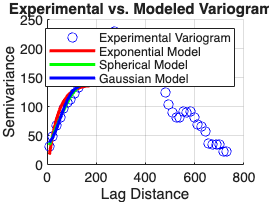


% Plot Comparison
figure; hold on;
scatter(bins, gamma, 'bo', 'DisplayName', 'Experimental Variogram');
plot(bins, gamma_exp, 'r-', 'LineWidth', 2, 'DisplayName', 'Exponential Model');
plot(bins, gamma_sph, 'g-', 'LineWidth', 2, 'DisplayName', 'Spherical Model');
plot(bins, gamma_gau, 'b-', 'LineWidth', 2, 'DisplayName', 'Gaussian Model');

xlabel('Lag Distance'); ylabel('Semivariance');
title('Experimental vs. Modeled Variograms');
legend show; grid on;

%%
% Fit an exponential variogram model
range = max(bins) / 3;  % Initial guess for range parameter
sill = max(gamma);       % Initial guess for sill
nugget = min(gamma);     % Initial guess for nugget

fitted_gamma = exponential_variogram(bins, nugget, range, sill);
sph_gamma = spherical_variogram(bins,nugget,range,sill);
gaussian_gamma = gaussian_variogram(bins,nugget,range,sill);

% RMSE of each variograms
disp(" various variogram rmse ");

 various variogram rmse 


E_exp0 = rmse(fitted_gamma, gamma);
E_sph0 = rmse(sph_gamma, gamma);
E_gau0 = rmse(gaussian_gamma, gamma);

disp(['RMSE for Exponential model: ', num2str(E_exp0)]);

RMSE for Exponential model: 104.5796


disp(['RMSE for Spherical model: ', num2str(E_sph0)]);

RMSE for Spherical model: 118.9936


disp(['RMSE for Gaussian model: ', num2str(E_gau0)]);

RMSE for Gaussian model: 126.3165


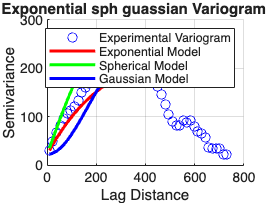

% Plot results
figure;
scatter(bins, gamma, 'bo', 'DisplayName', 'Experimental Variogram'); hold on;
plot(bins, fitted_gamma, 'r-', 'LineWidth', 2, 'DisplayName', 'Exponential Model');
hold on;
plot(bins, sph_gamma, 'g-', 'LineWidth', 2, 'DisplayName', 'Spherical Model');
hold on;
plot(bins, gaussian_gamma, 'b-', 'LineWidth', 2, 'DisplayName', 'Gaussian Model');
xlabel('Lag Distance');
ylabel('Semivariance');
legend;
title('Exponential sph guassian Variogram Fit');
grid on;
hold off;


%% Function: Compute Experimental Variogram
function [bins, gamma] = compute_variogram(x, y, values, nrbins)
    n = length(x);
    distances = [];
    semivariances = [];

    % Compute pairwise distances and squared differences
    for i = 1:n
        for j = i+1:n
            d = sqrt((x(i) - x(j))^2 + (y(i) - y(j))^2);
            gamma_ij = 0.5 * (values(i) - values(j))^2;
            distances = [distances; d];
            semivariances = [semivariances; gamma_ij];
        end
    end

    % Bin distances
    max_dist = max(distances);
    bin_edges = linspace(0, max_dist, nrbins+1);
    bins = zeros(nrbins, 1);
    gamma = zeros(nrbins, 1);
    
    for k = 1:nrbins
        in_bin = (distances >= bin_edges(k)) & (distances < bin_edges(k+1));
        if sum(in_bin) > 0
            bins(k) = mean(distances(in_bin));
            gamma(k) = mean(semivariances(in_bin));
        else
            bins(k) = NaN;
            gamma(k) = NaN;
        end
    end
    
    % Remove NaNs
    valid_idx = ~isnan(bins) & ~isnan(gamma);
    bins = bins(valid_idx);
    gamma = gamma(valid_idx);
end

%% Function: Exponential Variogram Model
function gamma_fit = exponential_variogram(bins, nugget, range, sill)
    gamma_fit = nugget + sill * (1 - exp(-bins / range));
end
%% function: spherical variogram model
function gamma_fit = spherical_variogram(bins,nugget,range,sill)
    gamma_fit = zeros(size(bins)); % Initialize output

    % Apply spherical model conditionally
    inside_range = bins <= range;
    gamma_fit(inside_range) = nugget + sill * (1.5 * (bins(inside_range) / range) - 0.5 * (bins(inside_range) / range).^3);
    
    % For bins > range, set to sill
    gamma_fit(~inside_range) = nugget + sill;;
end

%% function: gaussian model:
function gamma_fit = gaussian_variogram(bins,nugget,sill,range)
    gamma_fit = nugget + sill * (1 - exp(-(bins / range).^2));
end 
%% function: variogram error:
function error_val = variogram_error(params, bins, gamma_exp, model_type)
    nugget = params(1); range = params(2); sill = params(3);
    switch model_type
        case 'exponential'
            gamma_fit = exponential_variogram(bins, nugget, range, sill);
        case 'spherical'
            gamma_fit = spherical_variogram(bins, nugget, range, sill);
        case 'gaussian'
            gamma_fit = gaussian_variogram(bins, nugget, range, sill);
    end
    error_val = sum((gamma_exp - gamma_fit).^2); % Least squares error
end


%% Interpolation by Kriging method  %%

latitudes = str2double(data.Lattitude(:));
longitudes = str2double(data.Longitude(:));
rsrp_values = str2double(data.RSRP_54_(:));

lonGrid = linspace(min(longitudes), max(longitudes), 50);
latGrid = linspace(min(latitudes), max(latitudes), 50);
[LonGrid, LatGrid] = meshgrid(lonGrid, latGrid);
% Create interpolation function (using Inverse Distance Weighting or similar)
F = scatteredInterpolant(latitudes, longitudes, rsrp_values, 'linear', 'none');


% Interpolate RSRP values over the grid
%[lat_mesh, lon_mesh] = meshgrid(lat_grid, lon_grid);
rsrp_grid = F(LonGrid, LatGrid);

% Plot the coverage map
%figure;
contourf(LonGrid, LatGrid, rsrp_grid, 20, 'LineColor', 'none'); % Filled contour plot

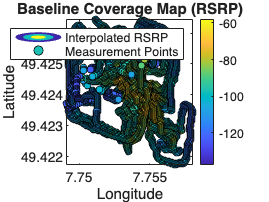

colorbar;
title('Baseline Coverage Map (RSRP)');
xlabel('Longitude');
ylabel('Latitude');

% Overlay measurement points
hold on;
scatter(longitudes, latitudes, 20, rsrp_values, 'filled', 'MarkerEdgeColor', 'k');
legend('Interpolated RSRP', 'Measurement Points');
hold off;

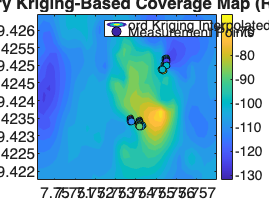


% Load the processed data


% Create a meshgrid for the grid
[lat_mesh, lon_mesh] = meshgrid(LatGrid, LonGrid);

% Define spatial points and values
spatial_points = [latitudes, longitudes];
grid_points = [lat_mesh(:), lon_mesh(:)];

% Perform Ordinary Kriging (OKD)
% Use MATLAB's fitrgp for Kriging if Geostatistics Toolbox is unavailable
% or create a custom covariance matrix and perform prediction
mdl = fitrgp(spatial_points, rsrp_values, 'KernelFunction', 'squaredexponential');

% Predict RSRP over the grid
predicted_rsrp = predict(mdl, grid_points);

% Reshape the predicted values to the grid format
kriging_rsrp_grid = reshape(predicted_rsrp, size(lat_mesh));

% Plot the Kriging-based coverage map
%figure;
contourf(lon_mesh, lat_mesh, kriging_rsrp_grid, 20, 'LineColor', 'none'); % Filled contour plot
colorbar;
title('Kriging-Based Coverage Map (RSRP)');
xlabel('Longitude');
ylabel('Latitude');

% Overlay measurement points
hold on;
scatter(longitudes, latitudes, 20, rsrp_values, 'filled', 'MarkerEdgeColor', 'k');
legend('Kriging Interpolated RSRP', 'Measurement Points');
hold off;

% Load the processed data
lat_grid = linspace(min(latitudes), max(latitudes), 30);  % 30 points instead of 50
lon_grid = linspace(min(longitudes), max(longitudes), 30);

% Create a meshgrid for interpolation points
[lat_mesh, lon_mesh] = meshgrid(lat_grid, lon_grid);
grid_points = [lat_mesh(:), lon_mesh(:)];  % Grid points as [latitude, longitude]

% Define spatial points and values
spatial_points = [latitudes, longitudes];
idx = randperm(length(latitudes), min(100, length(latitudes)));  % Use up to 500 points
spatial_points = [latitudes(idx), longitudes(idx)];
rsrp_values = rsrp_values(idx);
distance_matrix = pdist2(spatial_points, spatial_points);
% Step 1: Compute experimental variogram
distances = pdist2(spatial_points, spatial_points); % Pairwise distances
semi_variances = 0.5 * (rsrp_values - rsrp_values').^2; % Semi-variogram values
[distance_bins, ~, bin_indices] = histcounts(distances(:), 50); % Group distances
avg_variance = accumarray(bin_indices, semi_variances(:), [], @mean); % Average variance per bin


% Step 2: Fit a theoretical variogram model (e.g., Spherical model)
% Model parameters: Nugget, Sill, and Range
nugget = 0; % Minimal variance at zero distance
sill = max(avg_variance); % Variance plateau
range = max(distance_matrix(:)) * 0.3;  % Use 30% of max distance
%range = distance_bins(find(avg_variance < sill * 0.95, 1, 'first')); % Effective range
variogram_model = @(h) nugget + (sill - nugget) * (1.5 * (h / range) - 0.5 * (h / range).^3).*(h <= range) + sill*(h > range);
%compute covr matrix
cov_matrix = variogram_model(distance_matrix);
cov_matrix = [cov_matrix, ones(size(cov_matrix, 1), 1); ones(1, size(cov_matrix, 1)), 0]; % Add Lagrange multiplier
% Step 3: Kriging Interpolation
num_points = size(grid_points, 1);
kriged_values = zeros(num_points, 1);
kriged_values = zeros(size(grid_points, 1), 1);

% Parallel Kriging (OKD) for faster computation 
parfor i = 1:size(grid_points, 1)
    % Compute distances to grid point
    d_grid_to_points = pdist2(grid_points(i, :), spatial_points);
    gamma = variogram_model(d_grid_to_points);
    gamma = [gamma(:); 1];
    
    % Solve Kriging system
    weights = cov_matrix \ gamma;
    kriged_values(i) = weights(1:end-1)' * rsrp_values;
end


% Reshape the Kriged values into grid format
kriged_rsrp_grid = reshape(kriged_values, size(lat_mesh));

% Step 4: Plot the Ordinary Kriging map
%figure;
contourf(lon_mesh, lat_mesh, kriged_rsrp_grid, 20, 'LineColor', 'none'); % Filled contour plot
colormap("parula")
colorbar;
title('Ordinary Kriging-Based Coverage Map (RSRP)');
xlabel('Longitude');
ylabel('Latitude');
n = min([length(latitudes), length(longitudes), length(rsrp_values)]);
latitudes = latitudes(1:n);
longitudes = longitudes(1:n);
rsrp_values = rsrp_values(1:n);
assert(length(latitudes) == length(longitudes), 'Latitude and longitude arrays must have the same length.');
assert(length(latitudes) == length(rsrp_values), 'RSRP values must match the number of latitude/longitude points.');

% Normalize RSRP values for color mapping
c = rsrp_values(:);  % Ensure column vector
c = (c - min(c)) / (max(c) - min(c));  % Normalize to [0, 1]

% Scatter plot

hold on;
scatter(longitudes, latitudes, 20, rsrp_values, 'filled', 'MarkerEdgeColor', 'k');
legend('ord Kriging Interpolated RSRP', 'Measurement Points');
hold off;

%% RMSE Calculation in Kriging %%

[x, y] = projfwd(utmstruct, latitudes, longitudes);

rsrp_values = str2double(data.RSRP_54_(:));

latitudes = x;
longitudes = y;

%rsrp_values = normalize(rsrp_values); 
% Compute the experimental variogram
[bins, gamma] = compute_variogram(x, y, rsrp_values, 50);
%% optimized model 



% Initial Guess for Parameters: [nugget, range, sill]
init_params = [min(gamma), max(bins)/3, max(gamma)];  

% Fit models using optimization
exp_params = fminsearch(@(p) variogram_error(p, bins, gamma, 'exponential'), init_params);


% Compute Fitted Models
%gamma_exp = exponential_variogram(bins, exp_params(1), exp_params(2), exp_params(3));


% Choose model
selected_model = 'exponential'; 
switch selected_model
    case 'exponential'
         nugget = exp_params(1);
         range_param = exp_params(2);
         sill = exp_params(3);

% Define the exponential variogram model as a function handle
        variogram_model = @(h) exponential_variogram(h, nugget, range_param, sill);

%% --- Step 3: Construct the Kriging System ---
% Number of sample points:
n = length(x);

% Compute the distance matrix among sample points
D = pdist2([x, y], [x, y]);

% Build the variogram matrix (K) for sample points
K = variogram_model(D);

% Append the Lagrange multiplier to enforce unbiasedness:
K_augmented = [K, ones(n,1); ones(1,n), 0];

K_augmented = K_augmented + eye(size(K_augmented)) * 1e-6;
%% --- Step 4: Define a Grid for Interpolation ---
% Set the grid resolution (adjust numGridPoints to balance resolution and computation)


step_size = 20;  % Increase this from 10 or 1 to reduce computations
[Xq, Yq] = meshgrid(min(x):step_size:max(x), min(y):step_size:max(y));

D = pdist2([x, y], [x, y]);  % Compute all pairwise distances at once
D_pred = pdist2([Xq(:), Yq(:)], [x, y]); % Distances from grid to known points
%% --- Step 5: Ordinary Kriging Interpolation ---
num_neighbors = 20;  % Select only the 20 nearest neighbors
[idx, dist] = knnsearch([x, y], [Xq(:), Yq(:)], 'K', num_neighbors);
grid_points = [Xq(:), Yq(:)];
% Build Kriging system using only nearest neighbors
x_neighbors = x(idx);
y_neighbors = y(idx);
rsrp_neighbors = rsrp_values(idx);


m = size(grid_points, 1);


parpool; % Start parallel pool (if not already started)
num_points = numel(Xq);  % Number of grid points
predicted_rsrp = NaN(num_points, 1);

parfor i = 1:num_points
    % Find nearest neighbors
    [idx, dist] = knnsearch([x, y], [Xq(i), Yq(i)], 'K', num_neighbors);
    
    % Extract neighbor data
    x_neighbors = x(idx);
    y_neighbors = y(idx);
    rsrp_neighbors = rsrp_values(idx);
    
    % Compute distance matrix
    D_neighbors = pdist2([x_neighbors, y_neighbors], [x_neighbors, y_neighbors]);
    K_neighbors = variogram_model(D_neighbors);  % Compute variogram model
    
    % Solve Kriging system
    K_neighbors_aug = [K_neighbors, ones(num_neighbors, 1); ones(1, num_neighbors), 0];
    K_neighbors_aug = K_neighbors_aug + eye(size(K_neighbors_aug)) * 1e-4; % Regularization

    k_neighbors = variogram_model(dist'); % Compute covariances for prediction point
    
    % Solve for weights (lambda)
    lambda = K_neighbors_aug \ [k_neighbors; 1];

    % Compute predicted RSRP
    predicted_rsrp(i) = sum(lambda(1:end-1) .* rsrp_neighbors);
end
% Reshape into grid for plotting
predicted_rsrp_grid = reshape(predicted_rsrp, size(Xq));



%% --- Step 6: Plot the Coverage Map ---
figure;
imagesc([min(x), max(x)], [min(y), max(y)], predicted_rsrp_grid);
set(gca, 'YDir', 'normal');  % Fix image axis orientation
colorbar;
xlabel('Longitude');
ylabel('Latitude');
title('Ordinary Kriging Coverage Map expo model');


Xq_vec = Xq(:);   Yq_vec = Yq(:);
query_points = [Xq_vec, Yq_vec];
reference_points = [x_neighbors(:), y_neighbors(:)];
% Find the nearest measured RSRP for each predicted location
[idx, ~] = knnsearch(reference_points,query_points);

% Extract corresponding true RSRP values
rsrp_true = rsrp_values(idx);

% Compute RMSE and MAE
rmse = sqrt(mean((rsrp_true - predicted_rsrp).^2));
mae = mean(abs(rsrp_true - predicted_rsrp));

% Display results
fprintf('RMSE: %.2f dB\n', rmse);
fprintf('MAE: %.2f dB\n', mae);
%% --- Step 6: Reshape and Plot the Coverage Map ---

    
end

Starting parallel pool (parpool) using the 'Processes' profile ...


Error using parpool (line 132)
No default cluster available. Create a cluster and its associated profile.

% Plot Comparison
figure; hold on;
scatter(bins, gamma, 'bo', 'DisplayName', 'Experimental Variogram');
plot(bins, gamma_exp, 'r-', 'LineWidth', 2, 'DisplayName', 'Exponential Model');




xlabel('Lag Distance'); ylabel('Semivariance');
title('Experimental vs. Modeled Variograms');
legend show; grid on;
%%
% Fit an exponential variogram model
range = max(bins) / 3;  % Initial guess for range parameter
sill = max(gamma);       % Initial guess for sill
nugget = min(gamma);     % Initial guess for nugget

expo_gamma = exponential_variogram(bins, nugget, range, sill);

% Plot results
figure;
scatter(bins, gamma, 'bo', 'DisplayName', 'Experimental Variogram'); hold on;
plot(bins, expo_gamma, 'r-', 'LineWidth', 2, 'DisplayName', 'Exponential Model');


xlabel('Lag Distance');
ylabel('Semivariance');
legend;
title('Exponential Variogram Fit');
grid on;
hold off;


